# Process the intensity data from Idler

Theta = (0,2) degrees.

idx = 224

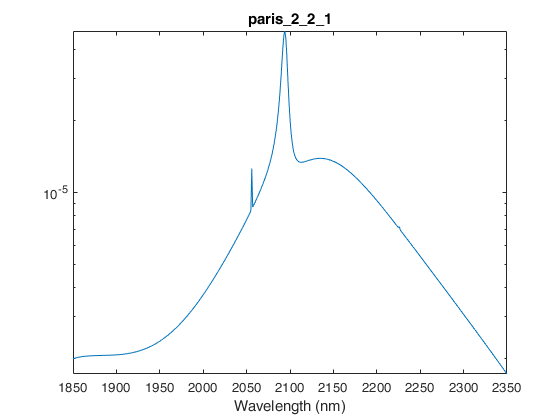

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config\sweeps');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));

cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
    "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
    "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
    "cylinder_dimer_no_substrate_110_13_6","cylinder_dimer_no_substrate_110_13_7",...
    "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
    "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12",...
    "cylinder_dimer_no_substrate_110_13_13"];
cylinder_dimer_no_substrate_111_28 = ["cylinder_dimer_no_substrate_111_28_1",...
    "cylinder_dimer_no_substrate_111_28_2","cylinder_dimer_no_substrate_111_28_3",...
    "cylinder_dimer_no_substrate_111_28_4","cylinder_dimer_no_substrate_111_28_5",...
    "cylinder_dimer_no_substrate_111_28_6","cylinder_dimer_no_substrate_111_28_7",...
    "cylinder_dimer_no_substrate_111_28_8","cylinder_dimer_no_substrate_111_28_9",...
    "cylinder_dimer_no_substrate_111_28_11","cylinder_dimer_no_substrate_111_28_12",...
    "cylinder_dimer_no_substrate_111_28_13"];
cylinder_dimer_no_substrate_110 = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_3","cylinder_dimer_no_substrate_110_4",...
    "cylinder_dimer_no_substrate_110_5","cylinder_dimer_no_substrate_110_6",...
    "cylinder_dimer_no_substrate_110_7","cylinder_dimer_no_substrate_110_8",...
    "cylinder_dimer_no_substrate_110_9","cylinder_dimer_no_substrate_110_10"];
cylinder_dimer_no_substrate_110_2_all = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_2_1","cylinder_dimer_no_substrate_110_2_2",...
    "cylinder_dimer_no_substrate_110_2_3",...
    "cylinder_dimer_no_substrate_110_2_4","cylinder_dimer_no_substrate_110_2_5"];

cylinder_dimer_substrate_111 = ["cylinder_dimer_substrate_111_1_1",...
    "cylinder_dimer_substrate_111_2_1","cylinder_dimer_substrate_111_3_1"];

cylinder_dimer_no_substrate_111_32_crosspol = ["cylinder_dimer_no_substrate_111_32_7",...
    "cylinder_dimer_no_substrate_111_32_8","cylinder_dimer_no_substrate_111_32_9",...
    "cylinder_dimer_no_substrate_111_32_16","cylinder_dimer_no_substrate_111_32_17",...
    "cylinder_dimer_no_substrate_111_32_18","cylinder_dimer_no_substrate_111_32_11",...
    "cylinder_dimer_no_substrate_111_32_12","cylinder_dimer_no_substrate_111_32_13"];
cylinder_dimer_no_substrate_111_32_copol = ["cylinder_dimer_no_substrate_111_32_19",...
    "cylinder_dimer_no_substrate_111_32_20","cylinder_dimer_no_substrate_111_32_21",...
    "cylinder_dimer_no_substrate_111_32_22","cylinder_dimer_no_substrate_111_32_23",...
    "cylinder_dimer_no_substrate_111_32_24","cylinder_dimer_no_substrate_111_32_25",...
    "cylinder_dimer_no_substrate_111_32_26","cylinder_dimer_no_substrate_111_32_27"];

cylinder_dimer_no_substrate_111_33_crosspol = ["cylinder_dimer_no_substrate_111_33_7",...
    "cylinder_dimer_no_substrate_111_33_8","cylinder_dimer_no_substrate_111_33_9",...
    "cylinder_dimer_no_substrate_111_33_16","cylinder_dimer_no_substrate_111_33_17",...
    "cylinder_dimer_no_substrate_111_33_18","cylinder_dimer_no_substrate_111_33_13",...
    "cylinder_dimer_no_substrate_111_33_11","cylinder_dimer_no_substrate_111_33_12"];
cylinder_dimer_no_substrate_111_33_copol = ["cylinder_dimer_no_substrate_111_33_19",...
    "cylinder_dimer_no_substrate_111_33_20","cylinder_dimer_no_substrate_111_33_21",...
    "cylinder_dimer_no_substrate_111_33_22","cylinder_dimer_no_substrate_111_33_23",...
    "cylinder_dimer_no_substrate_111_33_24","cylinder_dimer_no_substrate_111_33_25",...
    "cylinder_dimer_no_substrate_111_33_26","cylinder_dimer_no_substrate_111_33_27"];

cylinder_dimer_no_substrate_111_34_crosspol = ["cylinder_dimer_no_substrate_111_34_7",...
    "cylinder_dimer_no_substrate_111_34_8","cylinder_dimer_no_substrate_111_34_9",...
    "cylinder_dimer_no_substrate_111_34_16","cylinder_dimer_no_substrate_111_34_17",...
    "cylinder_dimer_no_substrate_111_34_18","cylinder_dimer_no_substrate_111_34_13",...
    "cylinder_dimer_no_substrate_111_34_11","cylinder_dimer_no_substrate_111_34_12"];
cylinder_dimer_no_substrate_111_34_copol = ["cylinder_dimer_no_substrate_111_34_19",...
    "cylinder_dimer_no_substrate_111_34_20","cylinder_dimer_no_substrate_111_34_21",...
    "cylinder_dimer_no_substrate_111_34_22","cylinder_dimer_no_substrate_111_34_23",...
    "cylinder_dimer_no_substrate_111_34_24","cylinder_dimer_no_substrate_111_34_25",...
    "cylinder_dimer_no_substrate_111_34_26","cylinder_dimer_no_substrate_111_34_27"];

enhancement_raw = [];
%for job = cylinder_dimer_substrate_111
%for job = cylinder_dimer_no_substrate_111_33_crosspol
for job = ["paris_2_2_1"]
    eval(job);
    load([options.output_dir_final 'derived_values.mat']);
    extra_options = matthew_extra_options(options);

    enhancement_raw = [enhancement_raw ];
    [~,idx] = max(derived_values.signal.scat_eff)
    wlengths = 299792458./derived_values.signal.freq;
    
    fig = figure;
    %yyaxis left;
    %plot(wlengths, derived_values.signal.scat_eff);
    %plot(derived_values.signal.scat_eff); % scat3_eff
    %hold on
    %ylabel('Linear Scattering Efficiency');
    %yyaxis right;
    %plot(wlengths, abs(derived_values.signal.sigma_fullup));
    %plot(wlengths, abs(derived_values.signal.sigma_fulldn));
    %plot(wlengths, abs(derived_values.signal.sigma_fullup)+abs(derived_values.signal.sigma_fulldn));
    semilogy(wlengths, (derived_values.sfg.scat3_eff));
    %plot(log10(derived_values.sfg.scat3_eff));
    %leg_scat3 = legend({'Signal','log_{10}(SFG)'});
    %leg_scat3.Location = 'southeast';
    xlabel('Wavelength (nm)');
    %ylabel('log_{10}(SFG)');
    axis tight;
    title(job, 'Interpreter', 'none');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
end